Rubén Vera Martínez, NIA: 241456

Sara Soriano Rossa, NIA: 240007

**PROBLEM 1**

**a) Calculate the sample standard deviation **$\hat{\sigma}$** for these weights and find the bias of **$\hat{\sigma}$**. **

X = SM22Lab4WeightsRunners{:,:};
theta_hat = std(X)

theta_hat = 7.7060

El bias de $\hat{\sigma}$ esta calculado en el apartado (b) una vez hemos realizado el Bootstrap.

**b) Use bootstrapping to find the bootstrap standard error for **$\hat{\sigma}$**.**

n = length(X);
B = 1e4;
theta_rep= zeros(1, B);
rng(0);
for j=1:B
    rs_indx = ceil(n*rand(1,n));
    X_boot = X(rs_indx);
    theta_rep(j) = std(X_boot);
end

bias = mean(theta_rep) - theta_hat;      
disp(['Bias of theta_hat: ' num2str(bias)]);

Bias of theta_hat: -0.48295


std_error = std(theta_rep);            
disp(['Bootstrap standard error for theta_hat: ' num2str(std_error)]);

Bootstrap standard error for theta_hat: 2.1846


Los resultados obtenidos han sido:

- Bias de nuestro estimador: -0.48295

- Standard Error de nuestro estimador: 2.1846

**c) Make a histogram of the bootstrap replications of **$\hat{\sigma}$** from (b). Inspect the data to try assessing why do we obtain such a strange histogram.**

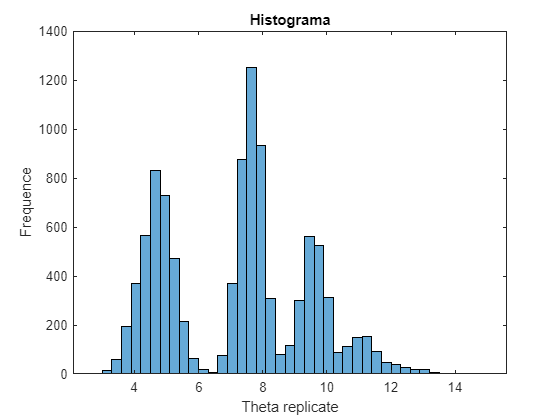

histogram(theta_rep);
hold on
title('Histograma');
xlabel('Theta replicate'); 
ylabel('Frequence');
hold off

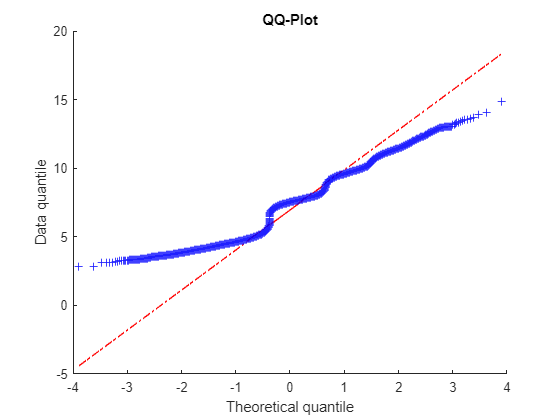


qqplot(theta_rep); % Refusem normalitat.
hold on
title('QQ-Plot');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

Debido a que la desviación estandar no es un estimador robusto, es muy sensible a los valores atípicos. En este caso, viendo los datos hemos observado que hay un valor muy lejos de la media y por lo tanto, existe un valor atípico que puede alterar considerablemente el histograma resultante. Por este motivo, el histograma se ve tan extraño.

**d) Suggest a way to improve the analysis so that you can compute a confidence interval using boot-strapping. Justify clearly why your proposal is adequate.**

Debido al resultado que hemos obtenido en el anterior histograma, queremos cambiar nuestros datos para generar un histograma menos extraño. La primera solución que nos hemos planteado es extraer los outliers ya que algunos datos son más altos o bajos que la mayoría. Pero hemos descartado esta idea ya que no hay motivo por el cual justificar que son outliers o no, ya que todos los datos que tenemos son posibles. Así que nuestra final propuesta es utilizar un estimador mucho más robusto que la desviación estándar para que el valor atípico no influya tanto en nuestros resultados. Para ello, buscando, hemos decidido usar el estimador Median Absolute Desviation (MAD).

Para obtener los resultados correctos con el nuevo estimador deberemos volver a realizar los anteriores apartados para realizar un nuevo Bootstrap con el nuevo estimador. A partir de ello, para estudiar si sigue una distribución Normal o no realizaremos de nuevo un histograma y un QQ-Plot.

**e) Implement the solution proposed in (d) and compute a confidence interval for **$\hat{\sigma}$**. Clearly indicate what method you choose to compute the interval.**

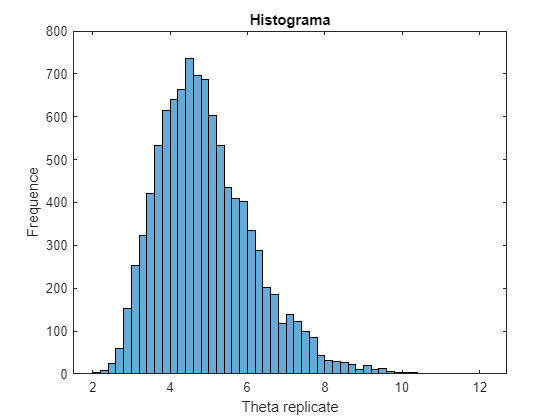

rng(0);
for j=1:B
    rs_indx = ceil(n*rand(1,n));
    X_boot = X(rs_indx);
    theta_rep(j) = mad(X_boot);
end
histogram(theta_rep);
hold on
title('Histograma');
xlabel('Theta replicate'); 
ylabel('Frequence');
hold off

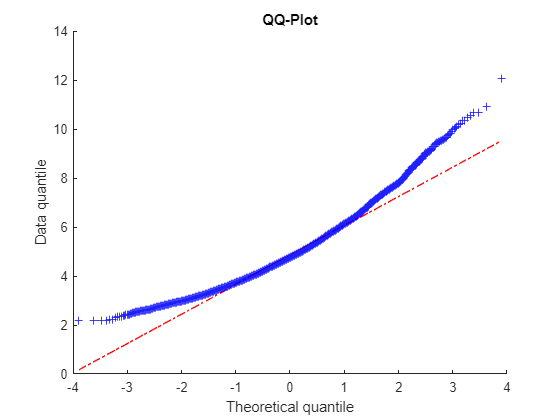


qqplot(theta_rep); % Refusem normalitat.
hold on
title('QQ-Plot');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

Como los datos replicados no siguen una distribución normal, el método usado será: Percentile-based method ya que no es necesario con este método asumir la normalidad de nuestros datos.

theta_hat = mad(X);
alpha = 0.05;
theta_biasCorrected = 2*theta_hat-mean(theta_rep)

theta_biasCorrected = 4.9562

theta_rep_sort = sort(theta_rep);
conf_interval = [2*theta_biasCorrected - theta_rep_sort(round((B)*(1-alpha/2))), 2*theta_biasCorrected-theta_rep_sort(round((B)*(alpha/2)));]

conf_interval =     2.1619    6.9120


**PROBLEM 3**

**a) Use bootstrapping to assess if the distribution of the sample skewness can be assumed normal. Clearly indicate your conclusion.**

Mirando los datos nos hemos fijado que en la fila 13 del Excel, en Matalb la 12 (porque no cogemos la fila de los nombres de las columnas) vemos que los valores estan intercambiados. Es decir, el valor que esta en Weight debería estar en Height y viceversa, porque no es posible tener esos resultados. Por lo tanto, la solución era o eliminar toda la fila o intercambiar los valores, hemos optado por la segunda opción.

X = SM22Lab4HeightandWeight{:,:};
%Intercambio en la fila mencionada previamente
temp = X(12,2);
X(12,2) = X(12,1);
X(12,1) = temp;
X(:,2) = X(:,2)/100; %Conversión a metros de la altura.
n = size(X, 1);
B = 1e4;
BMI = zeros(n,1);
for i=1:n
    BMI(i) = X(i,1)/(X(i,2)^2);
end
theta_hat = skewness(BMI)

theta_hat = 0.9834

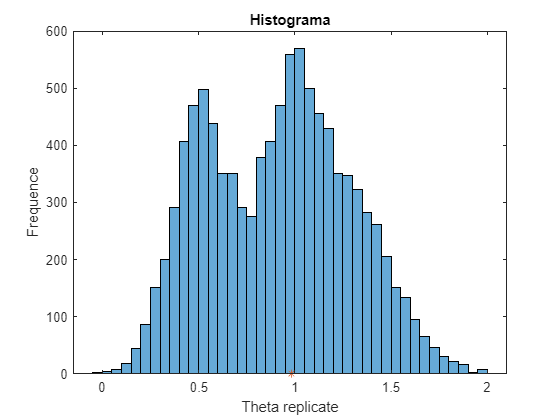

theta_rep = zeros(B, 1);
rng(0);
for j = 1:B
    rs_idx = ceil(n*rand(1,n));
    X_boot = BMI(rs_idx,:); 
    theta_rep(j) = skewness(X_boot);     % Sample skewness of each columnn in X
end

histogram(theta_rep);
hold on
plot(theta_hat, 0, '*');
title('Histograma');
xlabel('Theta replicate'); 
ylabel('Frequence');
hold off

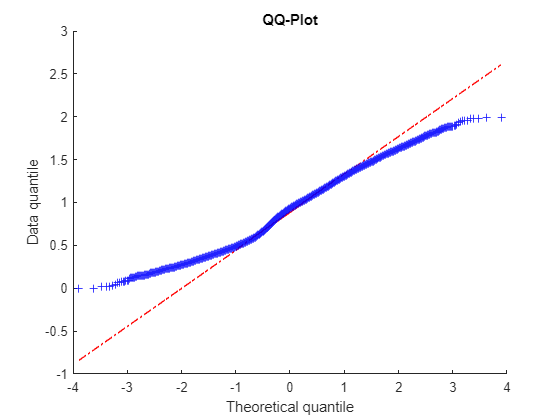


qqplot(theta_rep);
hold on
title('QQ-Plot');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

A partir del histograma i del QQ-Plot rechazamos que sigan una distribución Normal, debido a que con 10.000 replicates, si siguiese una Distribución Normal, veriamos que la linea azul de puntos estaria encima de la roja.

**b) Based on the bootstrap from (a), estimate the standard error and the bias of your estimator. **

bias = mean(theta_rep) - theta_hat;
disp(['Bias of our estimator: ' num2str(bias)]);

Bias of our estimator: -0.071182


std_error = std(theta_rep);            
disp(['Standard error of our estimator: ' num2str(std_error)]);

Standard error of our estimator: 0.37211


Los resultados obtenidos han sido:

- Bias de nuestro estimador: -0.071182

- Standard Error de nuestro estimador: 0.37211

**c) Estimate a 95% confidence interval for the skewness using student’s t. Based on your analysis from (b), discuss whether this is likely to be accurate or not. **

alpha = 0.05;
theta_biasCorrected = 2*theta_hat-mean(theta_rep)

theta_biasCorrected = 1.0546

conf_interval = [theta_biasCorrected-tinv(alpha/2, n-1)*std_error theta_biasCorrected+tinv(alpha/2, n-1)*std_error]

conf_interval =     1.7889    0.3203


Para realizar el intervalo de confianza usando Student's t, hemos de asumir la Normalidad de nuestros datos. En el apartado a) hemos rechazado el hecho de que nuestros replicates siguiesen una Distribución Normal. Por lo cual, el intervalo no será necesariamente muy preciso.

**d) Compute a 95% confidence interval for the skewness using the percentiles of the bootstrap distribution. Clearly indicate your conclusion regarding the research question.**

%percentile-based conf intervals
alpha = 0.05;
theta_rep_sort = sort(theta_rep);
conf_interval = [2*theta_biasCorrected - theta_rep_sort(round((B)*(1-alpha/2))), 2*theta_biasCorrected-theta_rep_sort(round((B)*(alpha/2)));]

conf_interval =     0.4901    1.8275


Una vez realizado nuestro experimento, vemos que el intervalo de confianza usando Percentiles, es: [0.4901, 1.8275]. Nuestra hipotesis nula era que la distribución era simétrica y, por lo tanto Skewness = 0. Al no estar el 0 dentro del intervalo de confianza, rechazamos la hipotesis nula. Esto quiere decir que la distribución, con un 95% de confianza no será simetrica. 